# Import Data Demo

This  scripts show how to change dinamically the data model using ThermoeconomicModel tool 

model=ThermoeconomicModel('cgam_model.json','CostTables','ALL');

INFO: cDataModel. Productive Structure is valid
INFO: cDataModel. Format Definition is valid
INFO: cDataModel. Exergy values [REF] are valid
INFO: cDataModel. Exergy values [T1180] are valid
INFO: cDataModel. Exergy values [ETG87] are valid
INFO: cDataModel. Exergy values [ECMP84] are valid
INFO: cDataModel. Exergy values [RP8] are valid
INFO: cDataModel. Exergy values [PINCH15] are valid
INFO: cExergyData. Process HRSG is not active
INFO: cDataModel. Exergy values [CGAMR] are valid
INFO: cExergyData. Process APH is not active
INFO: cDataModel. Exergy values [noAPH] are valid
INFO: cDataModel. Waste Definition is valid
INFO: cDataModel. Resources Cost sample [Base] is valid
INFO: cDataModel. Resources Cost sample [CGAMR] is valid
INFO: cDataModel. Data model cgam_model is valid
INFO: cThermoeconomicModel. Productive Diagram Active
INFO: cThermoeconomicModel. Set state REF
INFO: cThermoeconomicModel. Compute Diagram FP
INFO: cThermoeconomicModel. Compute thermoeconomic analysis for stat

model.showProperties;

              State: 'REF'
     ReferenceState: 'REF'
     ResourceSample: 'Base'
         CostTables: 'ALL'
    DiagnosisMethod: 'WASTE_EXTERNAL'
        ActiveWaste: 'QG'
            Summary: 'NONE'
          Recycling: 'false'
              Debug: 'true'
     IsResourceCost: 'true'
        IsDiagnosis: 'false'
          IsSummary: 'true'
            IsWaste: 'true'



showResults(model.DataModel)


Flows Data

 key   type      
———————————————————
 NG    RESOURCE  
 B1    RESOURCE  
 B2    INTERNAL  
 B3    INTERNAL  
 B4    INTERNAL  
 B5    INTERNAL  
 B6    INTERNAL  
 B7    INTERNAL  
 WC    INTERNAL  
 WN    OUTPUT    
 QV    OUTPUT    
 QG    WASTE     


Processes Data

 key    fuel    product   type         
—————————————————————————————————————————
 COMB   NG+B3   B4        PRODUCTIVE   
 CMP    WC      B2-B1     PRODUCTIVE   
 TRB    B4-B5   WC+WN     PRODUCTIVE   
 APH    B5-B6   B3-B2     PRODUCTIVE   
 HRSG   B6-B7   QV        PRODUCTIVE   
 STCK   B7      QG        DISSIPATIVE  


Exergy Data

 key          REF       T1180       ETG87      ECMP84         RP8     PINCH15       CGAMR       noAPH 
————————————————————————————————————————————————————————————————————————————————————————————————————————
 NG        72.465      73.327        73.6      73.297      72.283      72.465      72.465      97.896 
 B1             0           0           0           0           0  

#### 1. Create a new state

Use external file `ExergyData.csv `to create a new plant state `Test`

tbl=ImportData('ExergyData.csv');
val=tbl.getColumnValue(1);
model.addExergyData('Test',val);

INFO: cThermoeconomicModel. Set state Test
INFO: cThermoeconomicModel. Compute Diagram FP
INFO: cThermoeconomicModel. Compute thermoeconomic analysis for state Test
INFO: cThermoeconomicModel. Compute thermoeconomic diagnosis for state Test


model.showResults(cType.Tables.FLOW_GENERAL_COST);


Flows Generalized Cost - [Test/Base]

Key         B(MW)       C($/h)     Cin($/h)      Cz($/h)      Cr($/h)    c($/MWh)  cin($/MWh)   cz($/MWh)   cr($/MWh)
——————————————————————————————————————————————————————————————————————————————————————————————————————————————————————
NG         75.805     2274.150     2274.150        0.000        0.000     30.0000     30.0000      0.0000      0.0000
B1          0.000        0.000        0.000        0.000        0.000      0.0000      0.0000      0.0000      0.0000
B2         28.614     1716.829     1537.720      109.657       69.452     59.9996     53.7401      3.8323      2.4272
B3         48.095     2865.270     2589.711      166.433      109.126     59.5752     53.8457      3.4605      2.2690
B4        102.461     5217.327     4863.861      170.033      183.433     50.9201     47.4704      1.6595      1.7903
B5         38.784     1974.886     1841.090       64.362       69.434     50.9201     47.4704      1.6595      1.7903
B6         16.62

#### 2. Create a new resource sample

Use external files` ResourceFlow.csv` and `ResourceProcess.csv` to create a new resource sample

tbl=ImportData('ResourceFlows.csv');
rval=tbl.getColumnData(2);
tbl=ImportData('ResourceProcesses.csv');
pval=tbl.getColumnValue(2);
model.addResourceData('Test',rval,pval);

INFO: cThermoeconomicModel. Set resource sample Test
INFO: cThermoeconomicModel. Compute thermoeconomic analysis for state Test


model.showResults(cType.Tables.FLOW_GENERAL_COST);


Flows Generalized Cost - [Test/Test]

Key         B(MW)       C($/h)     Cin($/h)      Cz($/h)      Cr($/h)    c($/MWh)  cin($/MWh)   cz($/MWh)   cr($/MWh)
——————————————————————————————————————————————————————————————————————————————————————————————————————————————————————
NG         75.805     2653.175     2653.175        0.000        0.000     35.0000     35.0000      0.0000      0.0000
B1          0.000        0.000        0.000        0.000        0.000      0.0000      0.0000      0.0000      0.0000
B2         28.614     1989.370     1794.007      114.620       80.743     69.5244     62.6968      4.0057      2.8218
B3         48.095     3322.266     3021.329      174.070      126.867     69.0772     62.8200      3.6193      2.6378
B4        102.461     6065.528     5674.504      177.770      213.254     59.1984     55.3821      1.7350      2.0813
B5         38.784     2295.951     2147.939       67.290       80.722     59.1984     55.3821      1.7350      2.0813
B6         16.62

#### 3. Modify waste allocation

Change the waste allocation method, for Active Waste

model.setWasteType('RESOURCES');

INFO: cThermoeconomicModel. Set allocation of waste QG to RESOURCES
INFO: cThermoeconomicModel. Compute thermoeconomic analysis for state Test
INFO: cThermoeconomicModel. Compute thermoeconomic diagnosis for state Test


model.showResults(cType.Tables.FLOW_GENERAL_COST);


Flows Generalized Cost - [Test/Test]

Key         B(MW)       C($/h)     Cin($/h)      Cz($/h)      Cr($/h)    c($/MWh)  cin($/MWh)   cz($/MWh)   cr($/MWh)
——————————————————————————————————————————————————————————————————————————————————————————————————————————————————————
NG         75.805     2653.175     2653.175        0.000        0.000     35.0000     35.0000      0.0000      0.0000
B1          0.000        0.000        0.000        0.000        0.000      0.0000      0.0000      0.0000      0.0000
B2         28.614     1977.986     1794.007      114.620       69.359     69.1265     62.6968      4.0057      2.4240
B3         48.095     3312.208     3021.329      174.070      116.809     68.8680     62.8200      3.6193      2.4287
B4        102.461     6071.659     5674.504      177.770      219.385     59.2582     55.3821      1.7350      2.1412
B5         38.784     2298.272     2147.939       67.290       83.043     59.2582     55.3821      1.7350      2.1412
B6         16.62

res=model.thermoeconomicDiagnosis;
showResults(res,'dgn');


Diagnosis Summary - Test

Key         MF(MW)      ΔI(MW)      ΔR(MW)     ΔPt(MW)     MF*(MW)     MR*(MW)    ΔPt*(MW)
———————————————————————————————————————————————————————————————————————————————————————————
COMB        1.1794      1.1650      0.0000      0.0000     -0.5898      0.0000      0.0000
CMP        -0.0008     -0.0040      0.0000      0.0000     -0.0014      0.0000      0.0000
TRB        -0.0002     -0.0020      0.0000      0.0000     -0.0004      0.0000      0.0000
APH         0.6456      0.3420      0.0000      0.0000      1.0216      0.0000      0.0000
HRSG        0.0732      0.6546      0.0000      1.5754      0.1159      0.0000      3.5407
STCK        0.0000      0.0000     -0.3910      0.0000      0.0000     -0.7466      0.0000
ENV         1.8972      2.1556     -0.3910      1.5754      0.5459     -0.7466      3.5407



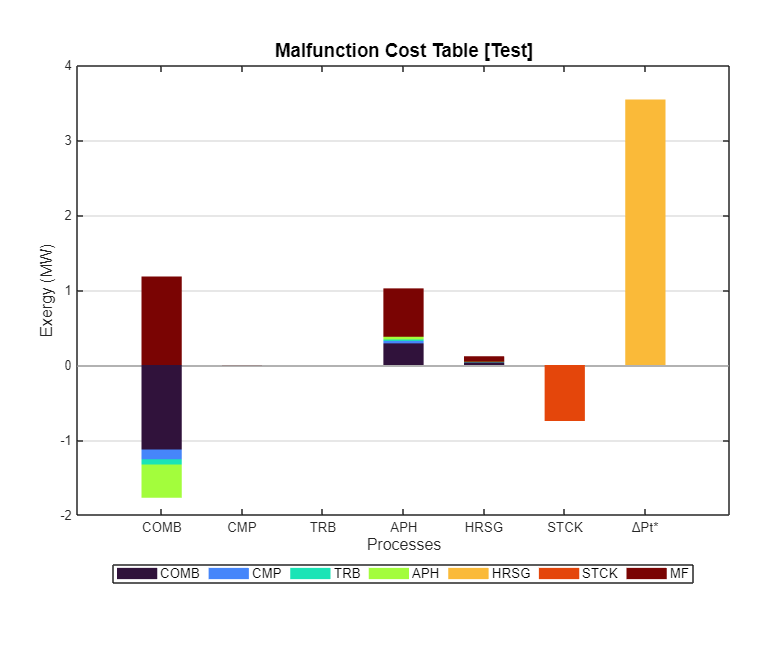

showGraph(res);

#### 4. Show the actual model parameters 

model.showProperties;

              State: 'Test'
     ReferenceState: 'REF'
     ResourceSample: 'Test'
         CostTables: 'ALL'
    DiagnosisMethod: 'WASTE_EXTERNAL'
        ActiveWaste: 'QG'
            Summary: 'NONE'
          Recycling: 'false'
              Debug: 'true'
     IsResourceCost: 'true'
        IsDiagnosis: 'true'
          IsSummary: 'true'
            IsWaste: 'true'



model.updateModel;
showResults(model.DataModel)


Flows Data

 key   type      
———————————————————
 NG    RESOURCE  
 B1    RESOURCE  
 B2    INTERNAL  
 B3    INTERNAL  
 B4    INTERNAL  
 B5    INTERNAL  
 B6    INTERNAL  
 B7    INTERNAL  
 WC    INTERNAL  
 WN    OUTPUT    
 QV    OUTPUT    
 QG    WASTE     


Processes Data

 key    fuel    product   type         
—————————————————————————————————————————
 COMB   NG+B3   B4        PRODUCTIVE   
 CMP    WC      B2-B1     PRODUCTIVE   
 TRB    B4-B5   WC+WN     PRODUCTIVE   
 APH    B5-B6   B3-B2     PRODUCTIVE   
 HRSG   B6-B7   QV        PRODUCTIVE   
 STCK   B7      QG        DISSIPATIVE  


Exergy Data

 key          REF       T1180       ETG87      ECMP84         RP8     PINCH15       CGAMR       noAPH        Test 
————————————————————————————————————————————————————————————————————————————————————————————————————————————————————
 NG        72.465      73.327        73.6      73.297      72.283      72.465      72.465      97.896      75.805 
 B1             0           0  